## 20016928, Aylin Öztürk

## Magic Tire Formula (Pacejka Model)

Normally, linear tire models are used for the simplicity of simulations. However, when dealing with large slip angles and ratios, a more accurate representation of tire behavior is needed. The Magic Tire Formula (Pacejka Model) is a non-linear tire model that captures the complex relationship between tire forces and slip conditions, especially under extreme driving conditions. This model includes large slip angles and ratios and provides mathematical expressions for three key forces or moments acting on a tire:

- **Longitudinal Force ****F****x****(****s****)**

- The force acting in the direction in which the wheel is moving.

- It depends on the slip ratio (s), which represents the difference between the wheel's rotational speed and the vehicle’s actual ground speed. As the slip ratio increases, the longitudinal force increases until it reaches a peak and then decreases.

- **Lateral Force F****y****(****α****)**

- The force acting sideways, perpendicular to the wheel’s direction. It affects the vehicle's steering and handling

- It depends on the slip angle (α\alphaα), which is the angle between the wheel's heading and the direction of travel. 

- **Self-Aligning Moment M****z****(****α****)**

- This is a torque (rotational force) that tries to return the tire to its original direction. 

- It also depends on the slip angle (α\alphaα) and is important for understanding the tire’s role in vehicle stability and handling.

### The general formula: 

Y(s)=D⋅sin[(C⋅arctan(B(s+Sh)−E⋅(B(s+Sh)−arctan(B(s+Sh)))))] +Sv

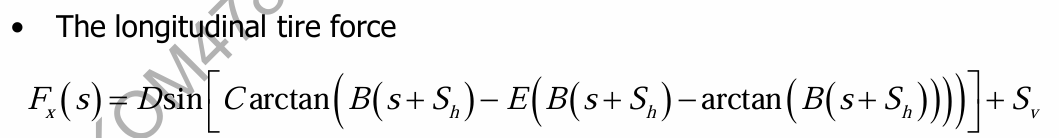

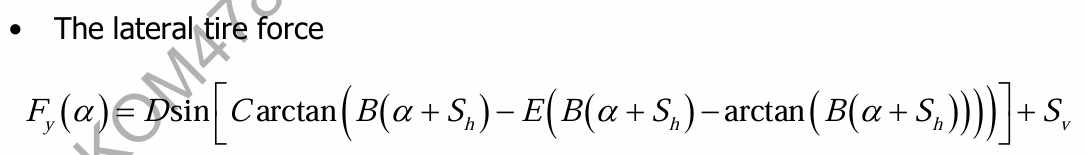

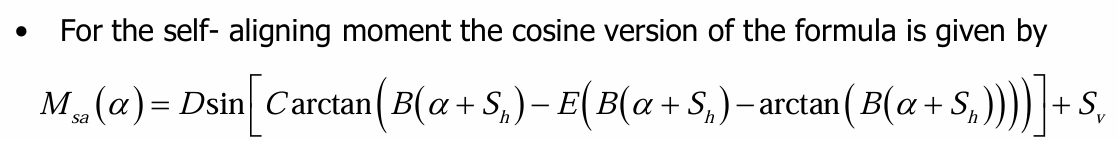

**α** (Slip angle): This is the angle between the direction of the tire and the direction of motion of the vehicle. It affects the lateral force on the tire.

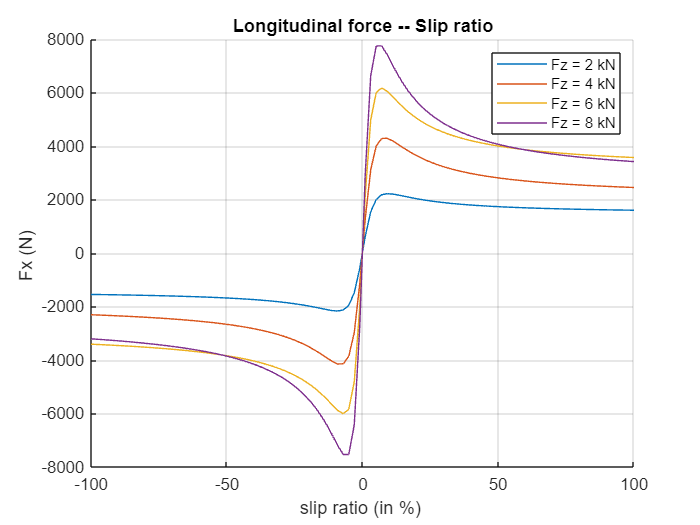

clear all; clc; close all; % clearing command window and workspace

%100 adet - daha pürüzsüz output plotu almak için seçildi
slip_ratio = linspace(-100, 100, 100 ); % varying between (-100%) - (100%)
slip_angle = linspace(-20, 20, 100); % varying between -20 t0 20 

Fz_values = [2, 4, 6, 8]; % giVen Fz values - vertical force applied on tire

% Columns: [Fz, B, C, D, E, Sh, Sv, BCD]
% Data from table (from homework sheet), introducing matrices
fy_values = [
    2, 0.244, 1.50, 1936, -0.132, -0.280, -118, 780.6;
    4, 0.239, 1.19, 3650, -0.678, -0.049, -156, 1038;
    6, 0.164, 1.27, 5237, -1.61, -0.126, -181, 1091;
    8, 0.112, 1.36, 6677, -2.16, 0.125, -240, 1017
]; %lateral force acting on tire

fx_values = [
    2, 0.178, 1.55, 2193, 0.432, 0.0, 25.0, 605.0;
    4, 0.171, 1.69, 4236, 0.619, 0.0, 70.6, 1224;
    6, 0.210, 1.67, 6090, 0.686, 0.0, 80.1, 2136;
    8, 0.214, 1.78, 7711, 0.783, 0.0, 104, 2937;
]; %longitudal force acting on tire

Msa_values = [
    2, 0.247, 2.56, -15.53, -3.92, -0.464, -12.5, -9.820;
    4, 0.234, 2.68, -48.56, -0.46, -0.082, -11.7, -30.45;
    6, 0.164, 2.46, -112.5, -2.04, -0.125, -6.00, -45.39;
    8, 0.127, 2.41, -191.3, -3.21, -0.009, -4.22, -58.55;
]; % self-aligning moment 

% Fx vs alip ratio plotting
figure;
hold on; %keeping the current plot and adding new plot
for i = 1:length(Fz_values)
    Fz = Fz_values(i); %assign corresponding Fz value from table 
    %assigning B,C,D,E,Sh,Sv,BCD values from the data set
    B = fx_values(i,2); C = fx_values(i,3); D = fx_values(i,4); E = fx_values(i,5); Sh=fx_values(i,6);
    Sv=fx_values(i,7);BCD= fx_values(i,8);
    
    % Pacejka (Magic Tire) Formula for Fx calculation
    Fx = D * sin(C * atan(B *((slip_ratio +Sh) - E * (B * (slip_ratio +Sh) - atan(B * (slip_ratio +Sh)))))) +Sv;
    
    plot(slip_ratio , Fx, 'DisplayName', sprintf('Fz = %d kN', Fz));
end
xlabel('slip ratio (in %) '); ylabel('Fx (N) '); title('Longitudinal force -- Slip ratio'); grid on;% labeling axis
legend; %adding legends on the plot
hold off; % clear old plots

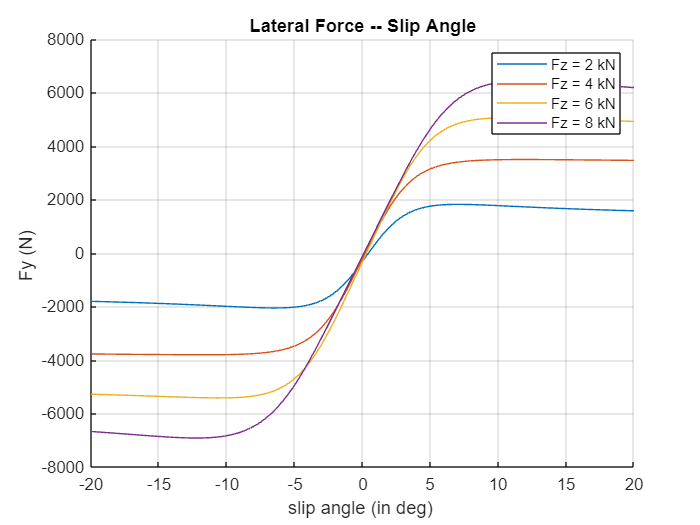


% Fy vs slip angle plottinh
figure;
hold on;
for i = 1:length(Fz_values)
    Fz = Fz_values(i);%assign corresponding Fz vertical force acting on the tire
    %assigning B,C,D,E,Sh,Sv,BCD values from the table
    B = fy_values(i,2); C = fy_values(i,3); D = fy_values(i,4); E = fy_values(i,5); Sh=fy_values(i,6);
    Sv=fy_values(i,7);BCD= fy_values(i,8);
    
     % Pacejka (Magic Tire) Formula for Fy calculation
    Fy = D * sin(C * atan(B * (slip_angle +Sh) - E * (B * (slip_angle +Sh) - atan(B * (slip_angle +Sh))))) +Sv;
    
    plot(slip_angle, Fy, 'DisplayName', sprintf('Fz = %d kN', Fz));
end
xlabel('slip angle (in deg) '); ylabel('Fy (N) '); title('Lateral Force -- Slip Angle'); grid on; %labeling the axis
legend;% adding legends on the plot
hold off; % clear old plots

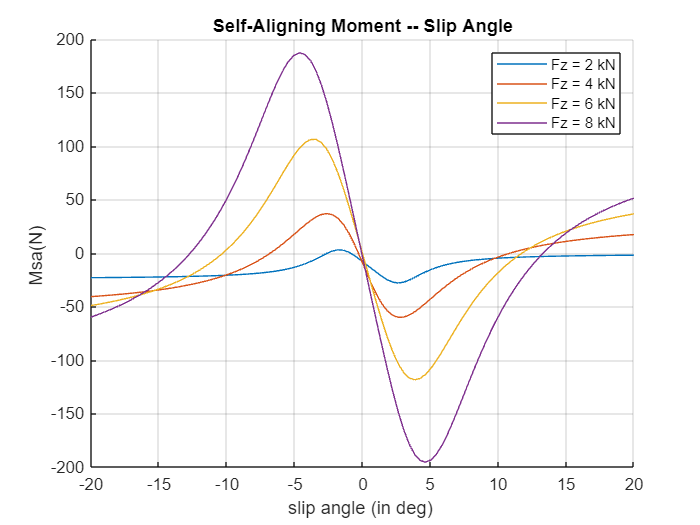


% Msa vs slip angle plotting
figure;
hold on;
for i = 1:length(Fz_values)
    Fz = Fz_values(i); %assign corresponding Fz value
    %assigning B,C,D,E,Sh,Sv,BCD values 
    B = Msa_values(i,2); C = Msa_values(i,3); D = Msa_values(i,4); E = Msa_values(i,5); Sh=Msa_values(i,6);
    Sv=Msa_values(i,7);BCD= Msa_values(i,8);
    
    %pacejka (Magic Tire) Formula for Msa calculation
    Msa = D * sin(C * atan(B * (slip_angle +Sh) - E * (B * (slip_angle +Sh) - atan(B * (slip_angle +Sh))))) +Sv;
    
    plot(slip_angle, Msa, 'DisplayName', sprintf('Fz = %d kN', Fz));
end
xlabel('slip angle (in deg) '); ylabel('Msa(N) '); title('Self-Aligning Moment -- Slip Angle'); grid on; %labeling the axis
legend; %adding legedns on the polt
hold off;